# Linear Feedback Control: Analysis and Design with MATLAB

著者: Dingyu Xue、 YangQuan Chen、 Derek P. Atherton

tau=1;
[n1,d1] = pade(tau,3);
G1 = tf(n1,d1);
[n2,d2] = paderm(tau,1,3); G2=tf(n2,d2)

c =      1    -1


c =     1.0000   -1.0000    0.5000


c =     1.0000   -1.0000    0.5000   -0.1667


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417


d =     1.0000    6.0000   18.0000   24.0000


G2 =
 
         -6 s + 24
  -----------------------
  s^3 + 6 s^2 + 18 s + 24
 
Continuous-time transfer function.



[n3,d3] = paderm(tau,2,5); G3=tf(n3,d3)

c =      1    -1


c =     1.0000   -1.0000    0.5000


c =     1.0000   -1.0000    0.5000   -0.1667


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002


d = 	1.0e+03 *

    0.0010    0.0150    0.1200    0.6000    1.8000    2.5200


G3 =
 
               60 s^2 - 720 s + 2520
  ------------------------------------------------
  s^5 + 15 s^4 + 120 s^3 + 600 s^2 + 1800 s + 2520
 
Continuous-time transfer function.



[n4,d4] = paderm(tau,3,7); G4=tf(n4,d4)

c =      1    -1


c =     1.0000   -1.0000    0.5000


c =     1.0000   -1.0000    0.5000   -0.1667


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002    0.0000


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002    0.0000   -0.0000


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002    0.0000   -0.0000    0.0000


d = 	1.0e+05 *

    0.0000    0.0003    0.0042    0.0420    0.2940    1.4112    4.2336    6.0480


G4 =
 
                     -840 s^3 + 2.016e04 s^2 - 1.814e05 s + 6.048e05
  --------------------------------------------------------------------------------------
  s^7 + 28 s^6 + 420 s^5 + 4200 s^4 + 2.94e04 s^3 + 1.411e05 s^2 + 4.234e05 s + 6.048e05
 
Continuous-time transfer function.



[n5,d5] = paderm(tau,4,9); G5=tf(n5,d5)

c =      1    -1


c =     1.0000   -1.0000    0.5000


c =     1.0000   -1.0000    0.5000   -0.1667


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002    0.0000


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002    0.0000   -0.0000


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002    0.0000   -0.0000    0.0000


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002    0.0000   -0.0000    0.0000   -0.0000


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002    0.0000   -0.0000    0.0000   -0.0000    0.0000


c =     1.0000   -1.0000    0.5000   -0.1667    0.0417   -0.0083    0.0014   -0.0002    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000


d = 	1.0e+08 *

    0.0000    0.0000    0.0000    0.0002    0.0021    0.0191    0.1270    0.5988    1.7963    2.5946


G5 =
 
                             1.512e04 s^4 - 6.048e05 s^3 + 9.979e06 s^2 - 7.983e07 s + 2.595e08
  -------------------------------------------------------------------------------------------------------------------------
  s^9 + 45 s^8 + 1080 s^7 + 1.764e04 s^6 + 2.117e05 s^5 + 1.905e06 s^4 + 1.27e07 s^3 + 5.988e07 s^2 + 1.796e08 s + 2.595e08
 
Continuous-time transfer function.



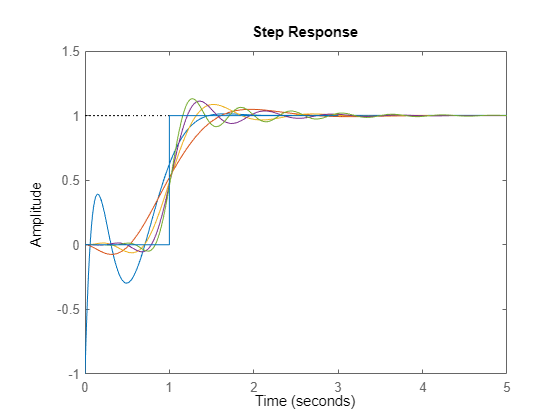

step(G1,G2,G3,G4,G5), line([0 1 1+eps 3], [0,0,1,1]) %x,y

% eps
% 
% ans =
% 
%    2.2204e-16

% draw a line from the point (3,15) to (2,12) 
% step(G1,G2,G3,G4,G5)
% line([0 1 1+eps 3], [0,0,1 1])

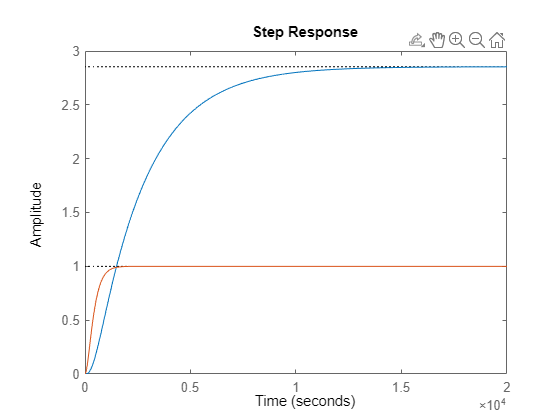

%%
K =2.854;
T = 2395;
L = 444.74; % むだ時間
num_P = K;
den_P = conv([T 1],[(L/2)^2 2*(L/2) 1]);
plant=tf(num_P,den_P);
%% Prue delay term
num_delay = 1;
den_delay = [(L/2)^2 2*(L/2) 1];
G6=tf(num_delay,den_delay);

figure,step(plant,G6),hold off


tau = L;
[NUM,DEN] = paderm(tau,0,2); G7=tf(NUM,DEN)

c =     1.0000 -444.7400


c = 	1.0e+04 *

    0.0001   -0.0445    9.8897


d =     1.0000    0.0045    0.0000


G7 =
 
           1.011e-05
  ----------------------------
  s^2 + 0.004497 s + 1.011e-05
 
Continuous-time transfer function.



[NUM1,DEN1] = paderm(tau,1,2); G8=tf(NUM1,DEN1)

c =     1.0000 -444.7400


c = 	1.0e+04 *

    0.0001   -0.0445    9.8897


c = 	1.0e+07 *

    0.0000   -0.0000    0.0099   -1.4661


d =     1.0000    0.0090    0.0000


G8 =
 
    -0.004497 s + 3.033e-05
  ----------------------------
  s^2 + 0.008994 s + 3.033e-05
 
Continuous-time transfer function.



[NUM2,DEN2] = paderm(tau,2,3); G9=tf(NUM2,DEN2)

c =     1.0000 -444.7400


c = 	1.0e+04 *

    0.0001   -0.0445    9.8897


c = 	1.0e+07 *

    0.0000   -0.0000    0.0099   -1.4661


c = 	1.0e+09 *

    0.0000   -0.0000    0.0001   -0.0147    1.6301


c = 	1.0e+11 *

    0.0000   -0.0000    0.0000   -0.0001    0.0163   -1.4499


d = 1×4
    1.0000    0.0202    0.0002    0.0000


G9 =
 
    0.006746 s^2 - 0.0001213 s + 6.821e-07
  ------------------------------------------
  s^3 + 0.02024 s^2 + 0.000182 s + 6.821e-07
 
Continuous-time transfer function.



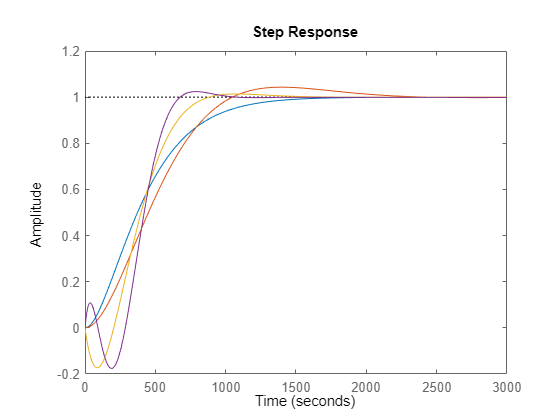

figure,step(G6,G7,G8,G9)

One can then obtain the time moments of the whole system by multiplying the two series to find a Pade approximation model of the original syatem, which is illustrated in the following; The step response is shown in Figure, from which it can be seen that approximation is not satisfactory.

G= tf([3,1],[1,3,3,1], 'ioDelay',2); c= timmomt(G,5);
c_hat=conv(c,cd);

Unrecognized function or variable 'c'.

Gr=pade_app(c_hat,1,3), step(G,Gr)
% line([0 1 1+eps 3], [0,0,1,1]) %x,y

%https://books.google.co.jp/books?id=oRmE0uR-ZRsC&pg=PA96&lpg=PA96&dq=pad%C3%A9+approximations+for+delay+matlab&source=bl&ots=i_GYeS4E99&sig=ACfU3U2Lw4wIOgjHEVWgUOFAhoxa7H2CeQ&hl=ja&sa=X&ved=2ahUKEwij4py9nvf1AhWss1YBHRX5D3M4ChDoAXoECBUQAw#v=onepage&q=pad%C3%A9%20approximations%20for%20delay%20matlab&f=false

function G_red=pademod(G_Sys,r,k)
c=timmomt(G_Sys,r+k+1);
G_red=pade_app(c,r,k);
end

function Gr=pade_app(c,r,k)
w = -c(r+2:r+k+1)';
vv = [c(r+1:-1:1)'; zeros(k-1-r,1)];
W = rot90(hankel(c(k+r:-1:r+1),vv));
V = rot90(hankel(c(r:-1:1)));
x = [1 (W\w)'];
dred = x(k+1:-1:1)/x(k+1);
y = [c(1) x(2:r+1)*V'+c(2:r+1)];
nred = y(r+1:-1:1)/x(k+1);
Gr = tf(nred,dred);
end

%

function [n,d]=paderm(tau,r,k)
c(1)=1;
for i=2:r+k+1
    c(i)=-c(i-1)*tau/(i-1)
end
Gr = pade_app(c,r,k);
n = Gr.num{1}(k-r+1:end);
d=Gr.den{1}
end

% function [nP,dP]=paderm(tau,r,m)
% c(1)=1; 
% for i=2:r+m+1
%     c(i)=-c(i-1)*tau/(i-1)
% end
% w=-c(r+2:m+r+1)';
% vv=[c(r+1:-1:1)'; zeros(m-1-r,1)];
% W = rot90(hankel(c(m+r:-1:r+1),vv));
% V = rot90(hankel(c(r:-1:1)));
% x = [1 (W\w)'];
% y = [1 x(2:r+1)*V'+c(2:r+1)];
% dP = x(m+1:-1:1)/x(m+1);
% nP = y(r+1:-1:1)/x(m+1);
% 
% end

https://books.google.co.jp/books?id=6d7iAAAAQBAJ&pg=PT236&lpg=PT236&dq=paderm+matlab&source=bl&ots=w6LJrPEMCV&sig=ACfU3U2o8fA093eWl4fMiStPePh3RBth2Q&hl=ja&sa=X&ved=2ahUKEwi19dzJovf1AhXNs1YBHTMOD2MQ6AF6BAgnEAM#v=onepage&q=paderm%20matlab&f=false